load("Sujeto2GrupoCantoCanto.mat")

flujo = data(:,1);        
resp = data(:,2);
pulso = data(:,3);
fs = 2000;
t = (1:1:length(flujo))/fs;

d = [1 20*fs;20*fs+1 50*fs; 50*fs+1 60*fs; 60*fs+1 75*fs]

d =            1       40000
       40001      100000
      100001      120000
      120001      150000


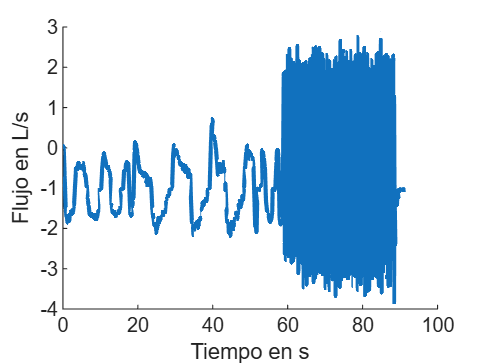

% Plotear toda la información
%Plot de flujo
hold off
clf
hold on
plot(t, flujo,'LineWidth',2)
xlabel('Tiempo en s')
ylabel('Flujo en L/s')
%Plot de respiración
hold off

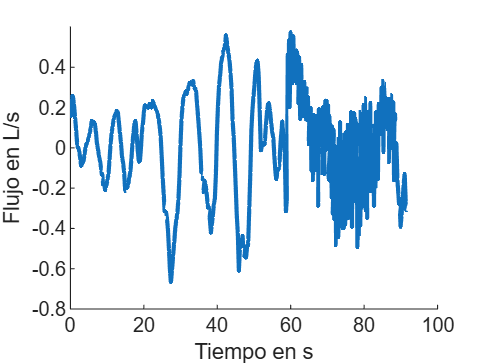

clf
hold on
plot(t, resp,'LineWidth',2)
xlabel('Tiempo en s')
ylabel('Flujo en L/s')
%Plot de pulso
hold off

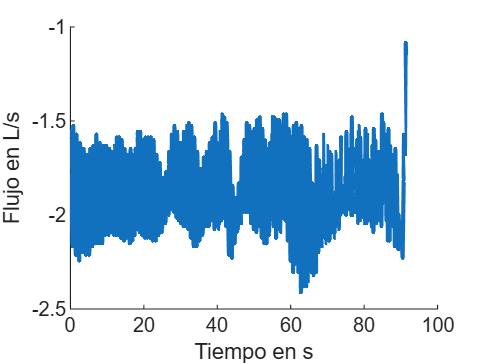

clf
hold on
plot(t, pulso,'LineWidth',2)
xlabel('Tiempo en s')
ylabel('Flujo en L/s')

%print('flujo', '-dpng', '-r300')

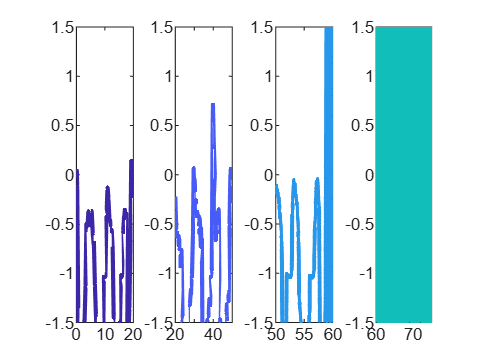

%Subplots de cada período del experimento para flujo, respiracion y pulso
clf
hold off
%Flujo
%hold on
col = colormap(parula(7));
for n =1:4
    st = d(n,1);
    en = d(n,2);
    t_n = t(st:en);
    f_n = flujo(st:en);
    subplot(1,4,n)
    plot(t_n,f_n,'LineWidth',2,'Color',col(n,:))
    ax = gca;
    ax.YLim = [-1.5 1.5];
    out = strcat("flujo_",num2str(n));
    %print(out,'-dpng','-r300')
end

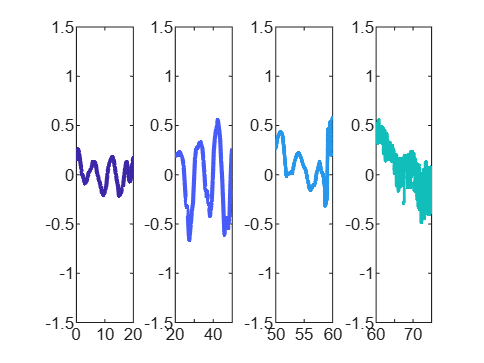

%Repiración
clf
hold off
%hold on
col = colormap(parula(7));
for n =1:4
    st = d(n,1);
    en = d(n,2);
    t_n = t(st:en);
    f_n = resp(st:en);
    subplot(1,4,n)
    plot(t_n,f_n,'LineWidth',2,'Color',col(n,:))
    ax = gca;
    ax.YLim = [-1.5 1.5];
    out = strcat("resp_",num2str(n));
    %print(out,'-dpng','-r300')
end

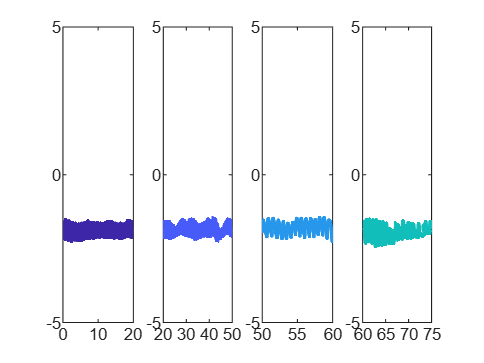

%Pulso
clf
hold off
%hold on
col = colormap(parula(7));
for n =1:4
    st = d(n,1);
    en = d(n,2);
    t_n = t(st:en);
    f_n = pulso(st:en);
    subplot(1,4,n)
    plot(t_n,f_n,'LineWidth',2,'Color',col(n,:))
    ax = gca;
    ax.YLim = [-5 5];
    out = strcat("pulso_",num2str(n));
    %print(out,'-dpng','-r300')
end

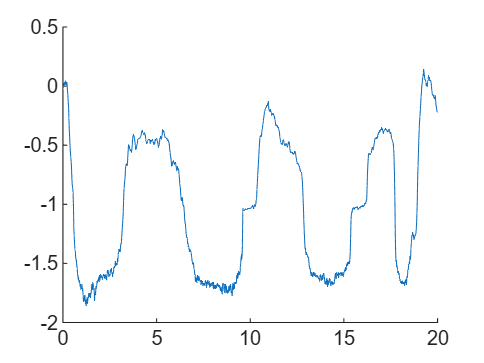

%Observar el período de control
%Flujo
clf
hold off
hold on
k = 1;
plot(t(d(k,1):d(k,2)),flujo(d(k,1):d(k,2)))

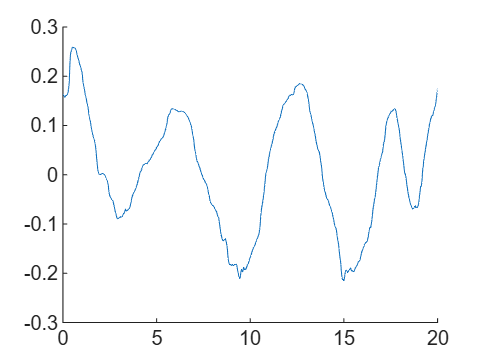

%Respiración
clf
hold off
hold on
k = 1;
plot(t(d(k,1):d(k,2)),resp(d(k,1):d(k,2)))

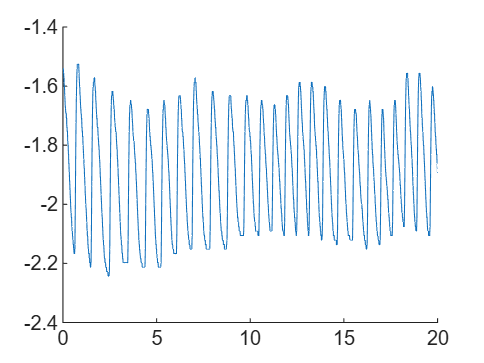

%Pulso
clf
hold off
hold on
k = 1;
plot(t(d(k,1):d(k,2)),pulso(d(k,1):d(k,2)))

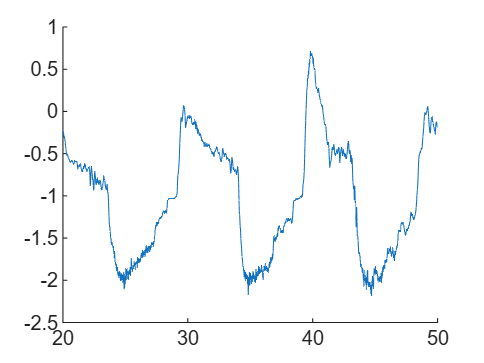

%Observar el período de respiración profunda
%Flujo
clf
hold off
hold on
k = 2;
plot(t(d(k,1):d(k,2)),flujo(d(k,1):d(k,2)))

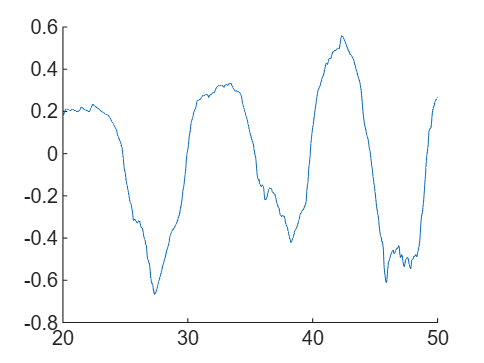

%Respiración
clf
hold off
hold on
k = 2;
plot(t(d(k,1):d(k,2)),resp(d(k,1):d(k,2)))

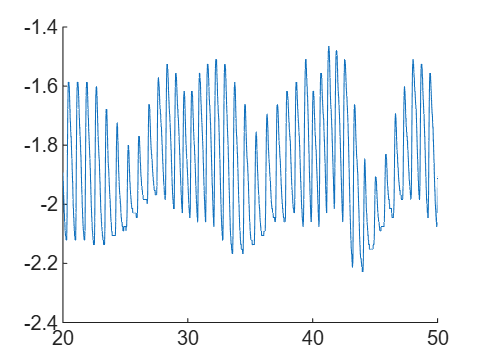

%Pulso
clf
hold off
hold on
k = 2;
plot(t(d(k,1):d(k,2)),pulso(d(k,1):d(k,2)))

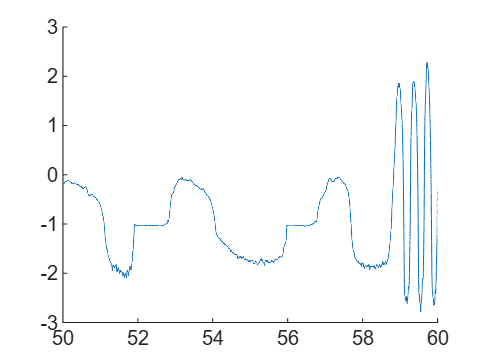

%Observar el período de descanso
%Flujo
clf
hold off
hold on
k = 3;
plot(t(d(k,1):d(k,2)),flujo(d(k,1):d(k,2)))

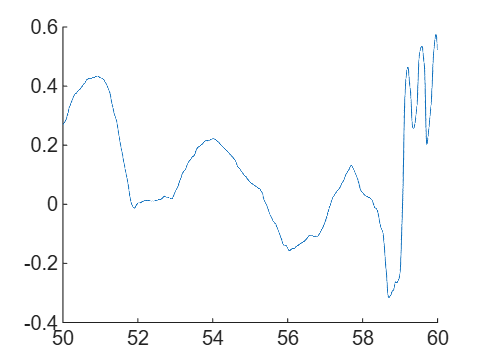

%Respiración
clf
hold off
hold on
k = 3;
plot(t(d(k,1):d(k,2)),resp(d(k,1):d(k,2)))

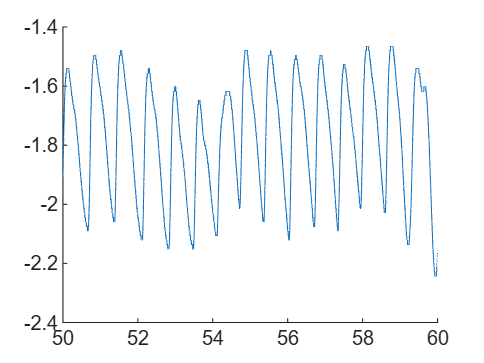

%Pulso
clf
hold off
hold on
k = 3;
plot(t(d(k,1):d(k,2)),pulso(d(k,1):d(k,2)))

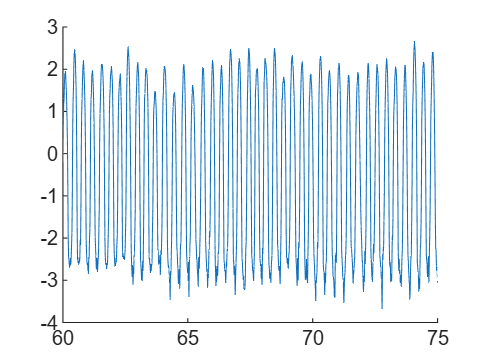

%Observar el período de respiración rápida
%Flujo
clf
hold off
hold on
k = 4;
plot(t(d(k,1):d(k,2)),flujo(d(k,1):d(k,2)))

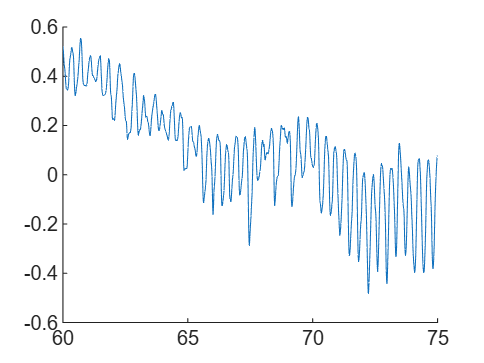

%Respiración
clf
hold off
hold on
k = 4;
plot(t(d(k,1):d(k,2)),resp(d(k,1):d(k,2)))

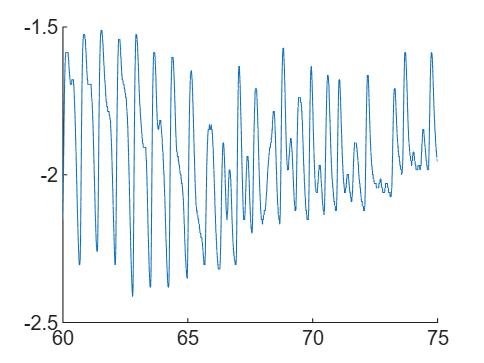

%Pulso
clf
hold off
hold on
k = 4;
plot(t(d(k,1):d(k,2)),pulso(d(k,1):d(k,2)))

%Espacio para comprobar los picos
% j puede ser de 1 a 4, representando cada período del análisis
% 1 = Reposo 1
% 2 = Profundo
% 3 = Reposo 2
% 4 = Rápido
% Las variables samp son la separación entre picos que pueden cambiar a
% discreción para confirmar bien cuántos mínimos y máximos hay en cada
% gráfica
j = 2;
%Flujo
sampf = 3000;
st = d(j,1);
en = d(j,2);
f_j = flujo(st:en);
flujoMax = (islocalmax(f_j,'MinSeparation',sampf) & (f_j>0.2));
flujoMin = (islocalmin(f_j,'MinSeparation',sampf)& (f_j<0));
fmax = find(flujoMax == 1);
fmin = find(flujoMin == 1);
fpicosMax = f_j(fmax);
fpicosMin = f_j(fmin);

hold off

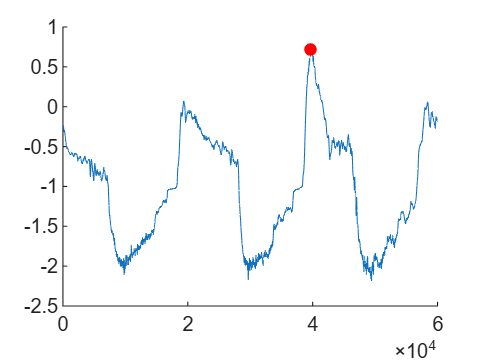

clf
hold on
plot(flujo(st:en))
plot(fmax,fpicosMax,'LineStyle','none','Marker','o','MarkerEdgeColor', 'none','MarkerFaceColor','r');
hold off

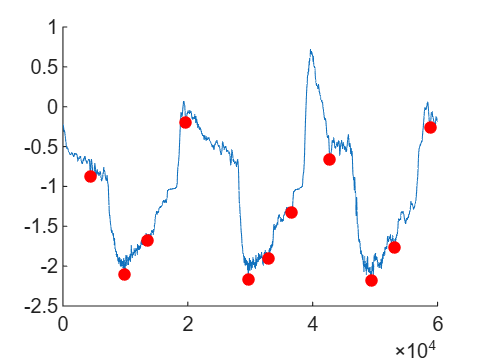

clf
hold on
plot(flujo(st:en))
plot(fmin,fpicosMin,'LineStyle','none','Marker','o','MarkerEdgeColor', 'none','MarkerFaceColor','r');

% Respiración
sampr = 3000;
r_j = resp(st:en);
respMax = (islocalmax(r_j,'MinSeparation',sampr));
respMin = (islocalmin(r_j,'MinSeparation',sampr));
rmax = find(respMax == 1);
rmin = find(respMin == 1);
rpicosMax = r_j(rmax);
rpicosMin = r_j(rmin);

hold off

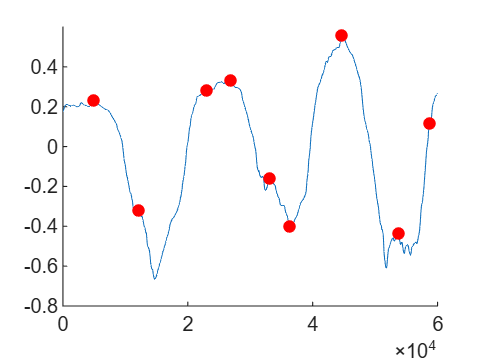

clf
hold on
plot(resp(st:en))
plot(rmax,rpicosMax,'LineStyle','none','Marker','o','MarkerEdgeColor', 'none','MarkerFaceColor','r');

%Pulso
sampp = 500;
p_j = pulso(st:en);
pulsoMax = (islocalmax(p_j,'MinSeparation',sampp));
pulsoMin = (islocalmin(p_j,'MinSeparation',sampp));
pmax = find(pulsoMax == 1);
pmin = find(pulsoMin == 1);
ppicosMax = p_j(pmax);
ppicosMin = p_j(pmin);

hold off

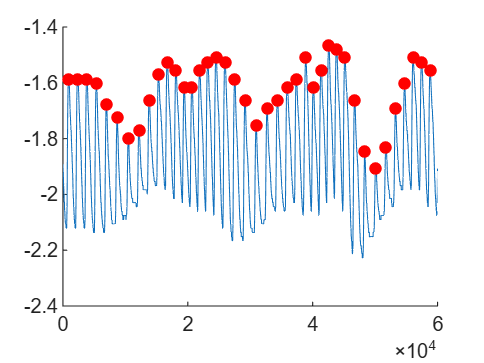

clf
hold on
plot(pulso(st:en))
plot(pmax,ppicosMax,'LineStyle','none','Marker','o','MarkerEdgeColor', 'none','MarkerFaceColor','r');


% get the peaks max + min for all semgments
%Flujo
picosf = cell(4,2);
%Aquí meten el dato que cambiaron en la sección de arriba, con el primero
%en el vector siendo el del período 1, luego el 2 y así se van.
%Van haciendo lo mismo con respiración y pulso.
p_sf = [3000, 4000, 1000, 1000];
for j = 1:4
    st = d(j,1);
    en = d(j,2);
    f_j = flujo(st:en);
    flujoMax = (islocalmax(f_j,'MinSeparation',p_sf(j)) & (f_j>0.2));
    flujoMin = (islocalmin(f_j,'MinSeparation',p_sf(j))& (f_j<0));
    fmax = find(flujoMax == 1);
    fmin = find(flujoMin == 1);
    fpicosMax = f_j(fmax);
    fpicosMin = f_j(fmin);
    picosf{j,1} = fpicosMax;
    picosf{j,2} = fpicosMin;
end
%Respiración
picosr = cell(4,2);
p_sr = [2000, 4000, 3000, 1000];
for j = 1:4
    st = d(j,1);
    en = d(j,2);
    r_j = resp(st:en);
    respMax = (islocalmax(r_j,'MinSeparation',p_sr(j)));
    respMin = (islocalmin(r_j,'MinSeparation',p_sr(j)));
    rmax = find(respMax == 1);
    rmin = find(respMin == 1);
    rpicosMax = r_j(rmax);
    rpicosMin = r_j(rmin);
    picosr{j,1} = rpicosMax;
    picosr{j,2} = rpicosMin;
end
%Pulso
picosp = cell(4,2);
p_sp = [1000, 1000, 900, 900];
for j = 1:4
    st = d(j,1);
    en = d(j,2);
    p_j = pulso(st:en);
    pulsoMax = (islocalmax(p_j,'MinSeparation',p_sp(j)));
    pulsoMin = (islocalmin(p_j,'MinSeparation',p_sp(j)));
    pmax = find(pulsoMax == 1);
    pmin = find(flujoMin == 1);
    ppicosMax = p_j(pmax);
    picosp{j,1} = ppicosMax;
end

%Resultados finales para el excel
%Las variables ..._m tienen los datos en orden para cada segmento del
%análisis, con flujo contando tanto con la media como con su +-desvest
%Respiración y pulso solo cuenta cuántos hubo en cada período
flujo_m = zeros(4,2);
for n =1:4
    fMax = picosf{n,1};
    fMin = picosf{n,2};
    if (length(fMax) == length(fMin))
        fampl = fMax - fMin;
    elseif(length(fMax)>length(fMin))
        fMax(end) = [];
    elseif(length(fMin)>length(fMax))
        fMin(end) = [];
    end
    flujo_m(n,1) = mean(fampl);
    flujo_m(n,2) = std(fampl);
end

Unrecognized function or variable 'fampl'.


resp_m = zeros(4,1);
for n = 1:4
    rmax = picosr{n,1};
    resp_m(n,1) = length(rmax);
end

pulso_m = zeros(4,1);
for n = 1:4
    pmax = picosp{n,1};
    pulso_m(n,1) = length(pmax);
end
